%Лабораторная работа 2
%Вариант 2
%Выполнила Жолнерович Арина Николаевна Б03-202в*
%Задание2
data=load('Шарики2.0.mat');
data=data.DATA.IMAGE

data = 1×1000 cell array
    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {500×290 int16}    {5

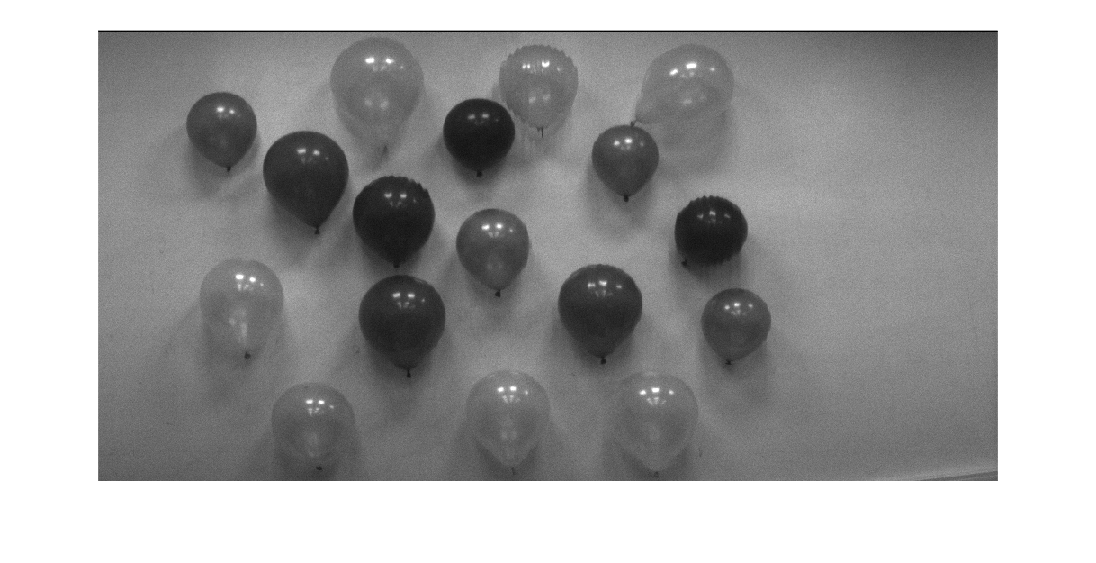

Hyper =zeros(500,1000,290);
for i =1:1000
    Hyper(end:-1:1,i,:) = double(data{i})/256;
end
% Использовать каналы от 120 до 290
imshow(double(Hyper(:,:,186)))

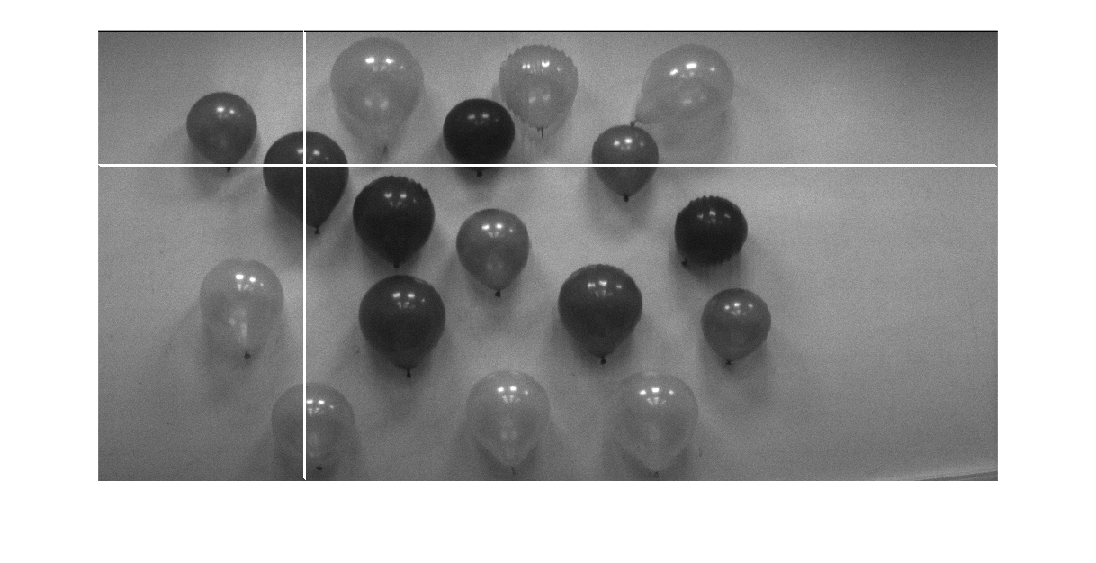


pic=double(Hyper);
x=230;
y=150;


for i =2:1000-2
    for j=2:500-2
        if i==x || j ==y
            Hyper(j,i,186)=1;
            Hyper(j-1,i-1,186)=1;
            Hyper(j+1,i+1,186)=1;
        end
    end
end
imshow(double(Hyper(:,:,186)))

%Гистограмма оранжевого 
his_orange=zeros(1,290);
for i=120:290
    his_orange(1,i)=pic(y, x, i);
end
his_orange

his_orange =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


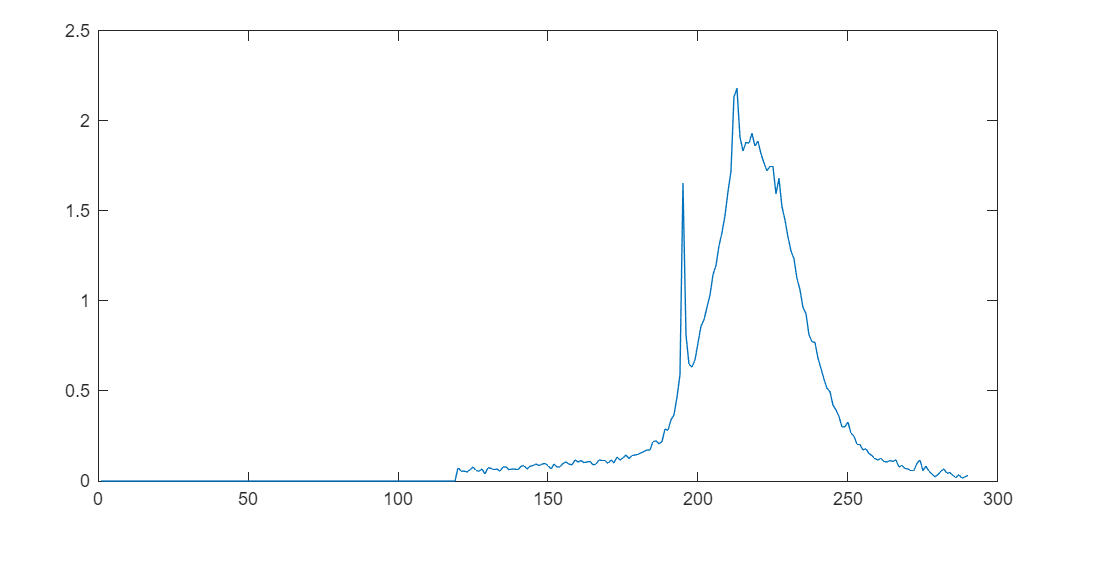

plot(his_orange)

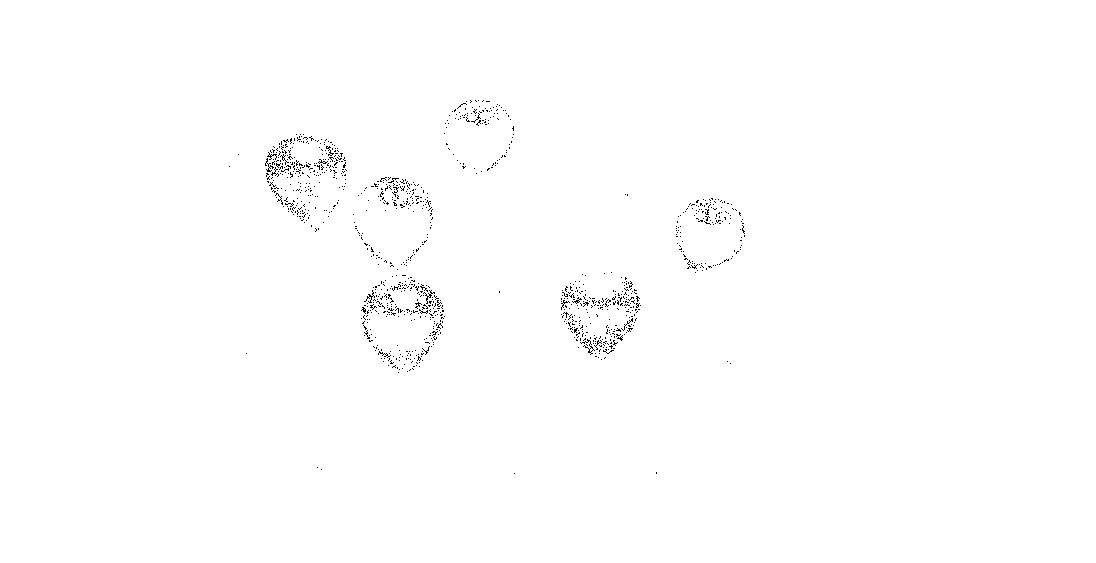

new_pic=zeros(500,1000);
for i =1:1000
    for j=1:500
        for n = 140:180
            if abs(his_orange(n)-pic(j,i,n))>0.05*his_orange(n)
                new_pic(j,i)=1;
            else
                new_pic(j,i)=0;
            end
        end
    end
end
imshow(new_pic)